Computation Vision - Project 1 Report

Topic B:  Railway inspection using on-train cameras

Authors:

- David Marafuz Gaspar - 106541 - david.marafuz.gaspar@tecnico.ulisboa.pt

- Pedro Gaspar Monico - 106626 - pedro.monico@tecnico.ulisboa.pt

Supervisors:

- Prof. Alexandra Moutinho

- Eng. Alexandre Athayde

## 1. Introduction

With the growth of railway systems in developed countries, and the recent expansion in developing nations, the safe and efficient operation of railway networks is paramount for passenger transport. To encourage the use of public transportation, it is very important to ensure the safety of the ridership. A critical aspect of this safety is ensuring that the track ahead is clear of obstructions, such as fallen trees, rocks, or debris, which could lead to catastrophic derailments. Traditionally, this inspection relies on periodic human patrols or trackside sensors, methods that can be time-consuming, costly, and lack the ability to provide real-time information to an oncoming train. Computer vision offers an alternative, as it can be automated without the high cost of continuous human resources.

This project aims to use image processing techniques to classify images of real railway tracks by detecting obstructions that could interfere with the passage of trains, ultimately enhancing the safety of this mode of transportation. The work will focus on several key problems: analyzing the images to characterize the appearance of the rails, and designing an algorithm to segment the image and isolate the rails. Subsequently, methods to determine whether the identified rail path is free of obstructions will be explored, not only checking if the rail itself is obstructed, but also detecting objects on the sides and in the area between the rails that could interfere with the train's path. The performance of the developed procedure will be quantitatively evaluated against our own annotated ground truth data using standard metrics.

This report is structured as follows: Sections 2 and 3 detail the methodology employed in the development pipeline covering the primary and secondary algorithms, respectively along with a discussion of the results. Finally, Section 4 concludes the report with a summary of findings.

**Attention**: In order to reduce clutter in the report, auxiliary scripts (specifically those implemented for subsequent processing steps and for plotting purposes) have been organized into separate files and are only referenced in the code when invoked. Auxiliary functions follow the naming convention `aux_<function>.m`, while plotting functions follow `plot_<function>.m`.

## **2. Rail Detection**

The first step in our railway obstruction detection pipeline is to accurately identify the rails in each image. Detecting the rails provides a reference framework for subsequent analysis, including the identification of obstacles on or near the track. In this stage, we compare different methods studied in theoretical and lab sessions to determine the most robust approach for line detection under varying lighting and background conditions.

The initial task involved examining the images and classifying them according to whether the rails were clearly visible. Since the dataset was relatively small, this manual classification was straightforward.

clear; clc; close all;

filenames = {
    './Data/cortada11.png',   ... % 1  - OBSTRUCTED (rocks)
    './Data/Frame1253.jpg',   ... % 2  - clear
    './Data/Frame1291.jpg',   ... % 3  - clear
    './Data/Frame1532.jpg',   ... % 4  - clear (curved)
    './Data/Frame1603.jpg',   ... % 5  - clear (curved)
    './Data/Frame1616.jpg',   ... % 6  - OBSTRUCTED (rocks)
    './Data/image00756.jpg',  ... % 7  - clear (station)
    './Data/image02293.jpg',  ... % 8  - clear (railroad crossing)
    './Data/image04054.jpg',  ... % 9  - OBSTRUCTED (rocks)
    './Data/image04925.jpg',  ... % 10 - clear (dark/tunnel)
    './Data/image06026.jpg',  ... % 11 - clear (tunnel exit)
    './Data/j30.jpg',         ... % 12 - OBSTRUCTED (rocks)
    './Data/l20.jpg',         ... % 13 - OBSTRUCTED (vegetation)
    './Data/l23.jpg',         ... % 14 - OBSTRUCTED (vegetation)
    './Data/p8.jpg',          ... % 15 - OBSTRUCTED (rocks beside track)
};

% Ground truth: 0 = clear, 1 = obstructed
labels = [1, 0, 0, 0, 0, 1, 0, 0, 1, 0, 0, 1, 1, 1, 1];

% Figure titles
descriptions = {
    'Obstructed - rocks', ...
    'Clear - straight', ...
    'Clear - straight', ...
    'Clear - curved', ...
    'Clear - curved', ...
    'Obstructed - rocks', ...
    'Clear - station', ...
    'Clear - railroad crossing', ...
    'Obstructed - rocks', ...
    'Clear - dark tunnel', ...
    'Clear - tunnel exit', ...
    'Obstructed - rocks', ...
    'Obstructed - vegetation', ...
    'Obstructed - vegetation', ...
    'Obstructed - rocks beside track', ...
};

N = length(filenames);

% Cell array accommodates images of different resolutions
images = cell(N, 1);
for i = 1:N
    images{i} = imread(filenames{i});
end

% Class distribution. Relevant in later phases
fprintf('\nTotal images:  %d\n', N);


Total images:  15


fprintf('Clear:         %d\n', sum(labels == 0));

Clear:         8


fprintf('Obstructed:    %d\n', sum(labels == 1));

Obstructed:    7


### 2.1. Grayscale Detection

For rail detection color information is not necessary since rails are primarily distinguished by their shape and intensity contrast with the background. All images were first converted to grayscale, focusing on the analysis of intensity variations

For visualization, we select a subset of representative images, chosen because they represent different scenarios: one is obstructed by rocks, one is a clear (unobstructed) scene, and another is a clear curve. The grayscale images and their corresponding histogram visualizations are then plotted to analyze the distribution of intensity values in each case. These histograms provide insight into the dynamic range of pixel intensities and reveal whether the images are underexposed, overexposed, or well-balanced. 

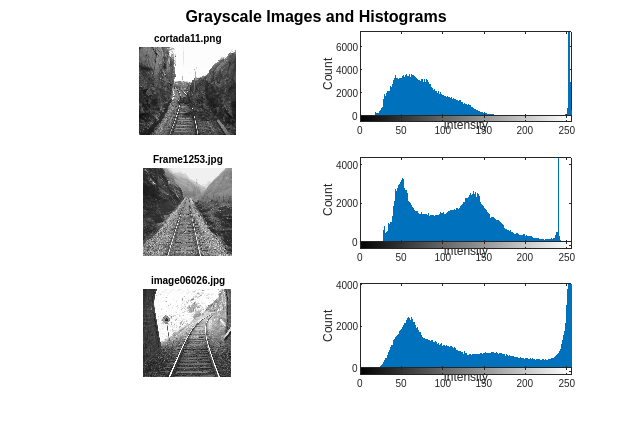

% Convert images to grayscale
images_gray = cell(N, 1);
for i = 1:N
    images_gray{i} = rgb2gray(images{i});
end

% Indices of selected images
SELECTED = [1, 2, 11];
N_plot = numel(SELECTED);

figure('Name', 'Grayscale Images and Histograms (selected)', ...
       'NumberTitle', 'off', 'Position', [100, 100, 1200, 800]);

for k = 1:N_plot
    i = SELECTED(k);

    % Display grayscale image
    subplot(N_plot, 2, (k-1)*2 + 1);
    imshow(images_gray{i});
    [~, name, ext] = fileparts(filenames{i});
    title(sprintf('%s', [name ext]), ...
          'FontSize', 8, 'Interpreter', 'none');

    % Display histogram
    subplot(N_plot, 2, (k-1)*2 + 2);
    imhist(images_gray{i});
    xlabel('Intensity', 'FontSize', 9);
    ylabel('Count', 'FontSize', 9);
end

sgtitle('Grayscale Images and Histograms', ...
        'FontSize', 12, 'FontWeight', 'bold');

The grayscale histograms reveal variations in image intensity and contrast across the dataset. Several images exhibit limited contrast, with pixel values concentrated in a narrow range, which can reduce the effectiveness of edge detection and line identification. These observations indicate that preprocessing steps such as histogram equalization or contrast enhancement are necessary to improve the visibility of rail boundaries

## 1.2. Image Enhancement

To improve the visibility of rails, we tested several image enhancement methods:

- Histogram Normalization

- Histogram Equalization

- Contrast Limited Adaptive Histogram Equalization (CLAHE)

Normalization scales the pixel intensities to the range [0,1]. This process redistributes the pixel values linearly and can sometimes improve contrast. Histogram equalization redistributes pixel intensities to achieve a uniform histogram. This can enhance global contrast and make features more distinguishable. 

CLAHE (Contrast Limited Adaptive Histogram Equalization) enhances image contrast by operating on small local regions rather than the entire image.  Although this method was not covered in class, MATLAB documentation recommends it for improving feature visibility, making it suitable for highlighting rail edges before line detection. For the images, we set CLAHE tiles to 8×8 to enhance local contrast without amplifying noise, and a clip limit of 0.02 to prevent over-enhancement while still highlighting rail edges.

Reference: MATLAB Documentation: *Contrast Limited Adaptive Histogram Equalization*: [https://www.mathworks.com/help/visionhdl/ug/contrast-adaptive-histogram-equalization.html](https://www.mathworks.com/help/visionhdl/ug/contrast-adaptive-histogram-equalization.html#d126e9140)

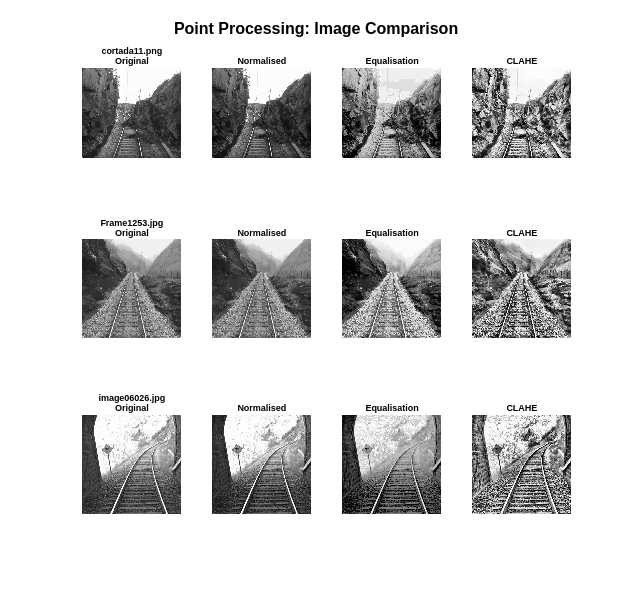

% Parameters
CLAHE_TILES     = [8 8];
CLAHE_CLIPLIMIT = 0.02;

images_norm  = cell(N,1);
images_eq    = cell(N,1);
images_clahe = cell(N,1);

% Process images
for i = 1:N
    img = images_gray{i};

    % Histogram Normalisation
    img_d = double(img);
    images_norm{i} = uint8(255*(img_d - min(img_d(:))) / (max(img_d(:)) - min(img_d(:))));

    % Histogram Equalisation
    images_eq{i} = histeq(img);

    % CLAHE
    images_clahe{i} = adapthisteq(img, ...
                                  'NumTiles', CLAHE_TILES, ...
                                  'ClipLimit', CLAHE_CLIPLIMIT, ...
                                  'Distribution', 'uniform');
end

% Plot Images
figure('Name', 'Point Processing: Images', ...
       'NumberTitle', 'off', 'Position', [0,0,1600,1500]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);
    img = images_gray{i};

    [~, name, ext] = fileparts(filenames{i});
    base_title = sprintf('%s', [name ext]);

    % Original
    subplot(length(SELECTED),4,(row_disp-1)*4 + 1);
    imshow(img);
    title(sprintf('%s\nOriginal', base_title), 'FontSize',7,'Interpreter','none');

    % Normalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 2);
    imshow(images_norm{i});
    title('Normalised','FontSize',7);

    % Equalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 3);
    imshow(images_eq{i});
    title('Equalisation','FontSize',7);

    % CLAHE
    subplot(length(SELECTED),4,(row_disp-1)*4 + 4);
    imshow(images_clahe{i});
    title('CLAHE','FontSize',7);
end

sgtitle('Point Processing: Image Comparison', ...
        'FontSize',12,'FontWeight','bold');

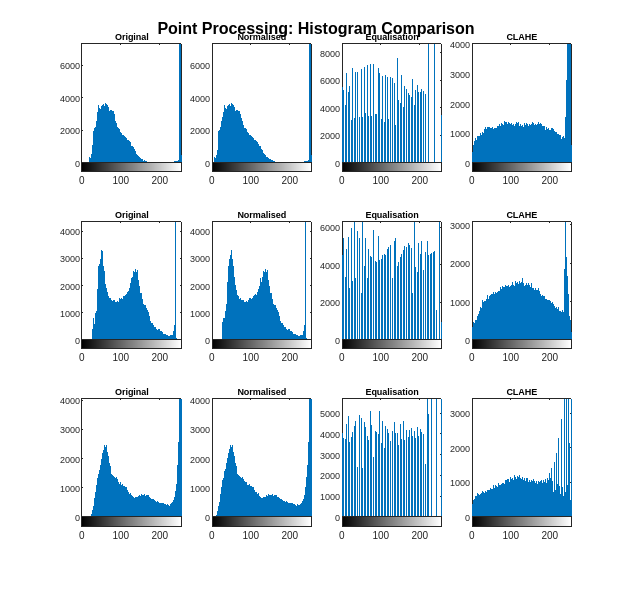


% Plot Histograms
figure('Name', 'Point Processing: Histograms', ...
       'NumberTitle', 'off', 'Position', [0,0,1600,1500]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);
    img = images_gray{i};

    % Original
    subplot(length(SELECTED),4,(row_disp-1)*4 + 1);
    imhist(img); set(gca,'FontSize',7);
    title(sprintf('Original'), 'FontSize',7);

    % Normalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 2);
    imhist(images_norm{i}); set(gca,'FontSize',7);
    title(sprintf('Normalised'), 'FontSize',7);

    % Equalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 3);
    imhist(images_eq{i}); set(gca,'FontSize',7);
    title(sprintf('Equalisation'), 'FontSize',7);

    % CLAHE
    subplot(length(SELECTED),4,(row_disp-1)*4 + 4);
    imhist(images_clahe{i}); set(gca,'FontSize',7);
    title(sprintf('CLAHE'), 'FontSize',7);
end

sgtitle('Point Processing: Histogram Comparison', ...
        'FontSize',12,'FontWeight','bold');

CLAHE produced the clearest and most consistent contrast enhancement across the dataset. As a result, the rails became significantly more distinguishable from the background, improving their visibility under different conditions. Compared to the other methods, CLAHE better preserved local details while enhancing contrast, making it the most effective approach for this application.

### 1.3. Image Filtering

After contrast enhancement, the next step in the pipeline is image filtering, whose main objective is to reduce noise while preserving relevant structures such as rail edges. Since railway images often contain texture, shadows, and small artifacts, filtering is essential to improve the robustness of subsequent edge and line detection stages.

To evaluate the most suitable approach, three different low-pass filters were tested on a representative subset of five images:

- Averaging filter

- Gaussian filter

- Median filter

These filters aim to smooth the image by attenuating high-frequency components, which are typically associated with noise.

The averaging filter is a simple uniform low-pass filter that replaces each pixel with the mean value of its surrounding neighborhood. The kernel size defines the size of the neighborhood, larger kernels increase smoothing but also increase edge blurring. 

The gaussian filter is a weighted low-pass filte**r** where pixels closer to the center have higher influence, following a Gaussian distribution. This results in smoother noise reduction with better edge preservation. The sigma controls the spread of the Gaussian. Lower values preserve details, while higher values produce stronger smoothing.

The median filter is a non-linear filter that replaces each pixel with the median value of its neighborhood. Larger kernels remove more noise but may distort fine details.

For a first analysis, we assigned a 5×5 kernel for the averaging filter, sigma 1.0 for the Gaussian filter, and a 5×5 neighborhood for the median filter, as these values provide a balanced initial smoothing effect. This configuration allows us to observe the relative impact of each filtering method on the images before fine tuning parameters for optimal contrast enhancement and edge preservation.

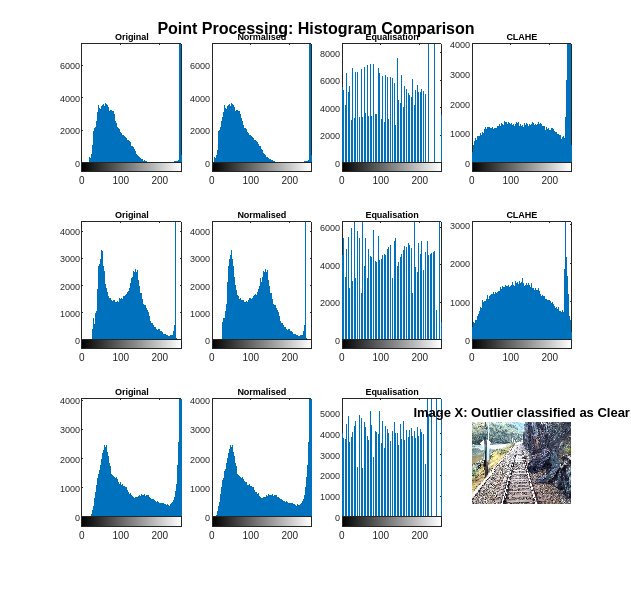

KERNEL_SIZE = 5;
sigma = 1;

figure('Name', 'Figure: Spatial Filter Comparison', ...
    'NumberTitle', 'off', ...
    'Position', [0, 0, 2800, 2400]);

for row = 1:length(SELECTED)
    i   = SELECTED(row);
    img = images_clahe{i};

    % Averaging filter
    h_avg   = fspecial('average', KERNEL_SIZE);
    img_avg = imfilter(img, h_avg, 'replicate');


    % Gaussian filter
    img_gauss = imgaussfilt(img, sigma);

    % Median filter
    img_med = medfilt2(img, [KERNEL_SIZE KERNEL_SIZE]);

    % Plot 
    subplot(5, 4, (row-1)*4 + 1);
    imshow(img);
    title(sprintf('CLAHE'), 'FontSize', 6, 'Interpreter', 'none');

    subplot(5, 4, (row-1)*4 + 2);
    imshow(img_avg);
    title(sprintf('Averaging %dx%d', KERNEL_SIZE, KERNEL_SIZE), 'FontSize', 6);

    subplot(5, 4, (row-1)*4 + 3);
    imshow(img_gauss);
    title('Gaussian (\sigma=1)', 'FontSize', 6);

    subplot(5, 4, (row-1)*4 + 4);
    imshow(img_med);
    title(sprintf('Median %dx%d', KERNEL_SIZE, KERNEL_SIZE), 'FontSize', 6);
end

sgtitle('Spatial Filter Comparison', ...
    'FontSize', 12, 'FontWeight', 'bold');

Although effective at reducing noise, the average filter treats all pixels equally, which leads to significant edge blurring. In our application, this caused the rail boundaries to become less distinct, negatively impacting line detection. The Gaussian filter provides a smoother and more natural blur compared to the averaging filter. It reduces noise effectively while maintaining edge continuity, which is crucial for detecting rail lines. The median filter is particularly effective at removing impulse noise (salt-and-pepper noise) while preserving edges. However, in our dataset the noise was not predominantly impulsive and the filter introduced slight distortions in linear structure. As a result, although edges were preserved, the continuity of rail lines was sometimes degraded.

Therefore, the Gaussian filter was selected as the most suitable method for this application.

#### 1.3.1 Gaussian Parameter Optimization

To further refine the performance of the Gaussian filter, different values of the standard deviation, σ, were tested: σ ∈ {0.5, 1, 2, 3}.

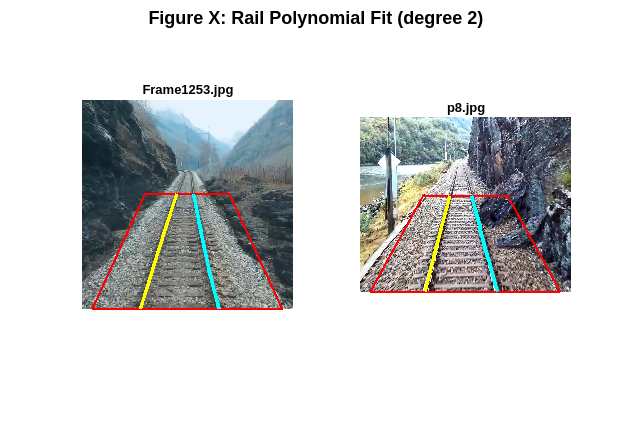

SIGMAS = [0.5, 1, 2, 3];

figure('Name', 'Figure: Gaussian Sigma Comparison', ...
    'NumberTitle', 'off', ...
    'Position', [0, 0, 2000, 1100]);


for row = 1:length(SELECTED)
    i   = SELECTED(row);
    img = images_clahe{i};
    base_title = sprintf('%s', [name ext]);

    % CLAHE input
    subplot(5, 5, (row-1)*5 + 1);
    imshow(img);
    title(sprintf('CLAHE'), ...
        'FontSize', 6, 'Interpreter', 'none');

    % Gaussian sigmas
    for s = 1:length(SIGMAS)
        sigma = SIGMAS(s);
        img_g = imgaussfilt(img, sigma);
        subplot(5, 5, (row-1)*5 + s + 1);
        imshow(img_g);
        title(sprintf('\\sigma = %.1f', sigma), 'FontSize', 6);
    end
end

sgtitle('Gaussian \sigma Comparison  (\sigma \in {0.5, 1, 2, 3})', ...
    'FontSize', 12, 'FontWeight', 'bold');

After evaluating different values of the Gaussian standard deviation, it was observed that small values, such as σ = 0.5, provided insufficient smoothing, leaving noise largely unfiltered. Higher values, including σ = 1.5 and σ = 2, introduced excessive blurring that diminished important rail edge details. A standard deviation of σ = 1 offered the optimal balance, effectively reducing noise while preserving clear and continuous rail edges.

### 1.4. Edge Enhancement

The next phase focused on edge enhancement to improve the visibility of the rails, facilitating more accurate line detection. Two approaches were considered: Unsharp Masking and the Difference of Gaussians (DoG) filter.

Unsharp Masking works by subtracting a blurred version of the image from the original, which emphasizes high-frequency details and sharpens edges. The degree of enhancement can be controlled by adjusting the amount of sharpening and the radius of the Gaussian blur.

The Difference of Gaussians (DoG) filter, which was discussed in theoretical classes as a pre-step for SIFT algorithm, was also evaluated experimentally on our railway images, since it highlights edges making rail boundaries more pronounced while effectively suppressing low-frequency background variations.

The DoG was computed by subtracting a Gaussian-smoothed image with σ₁ from a coarser one with σ₂ = 2·σ₁. For Unsharp Masking, an amount of 1 was used, meaning the extracted edge signal is added back to the image at full weight, providing a balanced sharpening without over-amplifying noise.

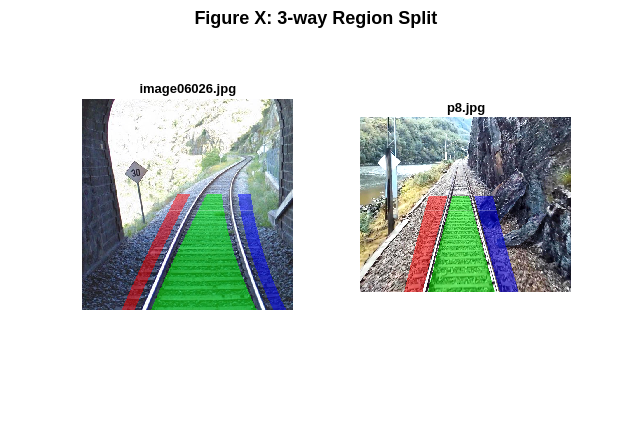

%  Parameters
sigma = 1;

images_gauss = cell(N, 1);
images_dog   = cell(N, 1);
images_us    = cell(N, 1);

for i = 1:N
    img = images_clahe{i};


    % Gaussian
    img_g = imgaussfilt(img, sigma);
    images_gauss{i} = img_g;

    % DoG
    img_g2  = imgaussfilt(img, sigma * 2);
    img_dog = imsubtract(img_g2, img_g);
    images_dog{i} = mat2gray(img_dog);

    % Unsharp Mask
    img_us = imsharpen(img_g, 'Radius', sigma, 'Amount', 1);
    images_us{i} = img_us;
end

figure('Name', 'Edge Enhancement', ...
       'NumberTitle', 'off', ...
       'Position', [0, 0, 3*200, length(SELECTED)*200]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);

    subplot(length(SELECTED), 3, (row_disp-1)*3 + 1);
    imshow(images_gauss{i});
    title(sprintf('Gaussian'), 'FontSize', 8);

    subplot(length(SELECTED), 3, (row_disp-1)*3 + 2);
    imshow(images_dog{i});
    title(sprintf('DoG'), 'FontSize', 8);

    subplot(length(SELECTED), 3, (row_disp-1)*3 + 3);
    imshow(images_us{i});
    title(sprintf('Unsharp Masking'), 'FontSize', 8);
end

sgtitle('Edge Enhancement: DoG and Unsharp Masking', ...
        'FontSize', 12, 'FontWeight', 'bold');

The DoG filter successfully isolated structural edges, such as rails, rock contours, and vegetation boundaries appearing as bright contours on a dark background. Unsharp Masking, in contrast, preserved the overall image appearance while enhancing edge contrast, yielding a perceptually sharper result. As the differences between methods are hard to compare at this stage, the three will be further evaluated to draw a more informed conclusion on the optimal filter for this dataset.

### 1.5. Edge Detection

After edge enhancement, the next step in the pipeline is edge detection, whose main objective is to highlight the rail boundaries and other relevant structures within the images. Clear edge information is essential for accurate line detection, particularly for subsequent Hough transform analysis.

To evaluate the most suitable approach, several classical edge detectors were tested:

- Prewitt

- Sobel

- Canny

These methods aim to identify areas of rapid intensity change, which correspond to potential rail edges. The Prewitt and Sobel operators compute first-order derivatives in the horizontal and vertical directions, producing gradient maps that indicate edge presence. Canny uses multi-stage detection with gradient calculation, non-maximum suppression, and hysteresis thresholding, which generally produces thin, connected edges.

In our preliminary analysis, we applied these detectors on both the Gaussian and Unsharp images. 

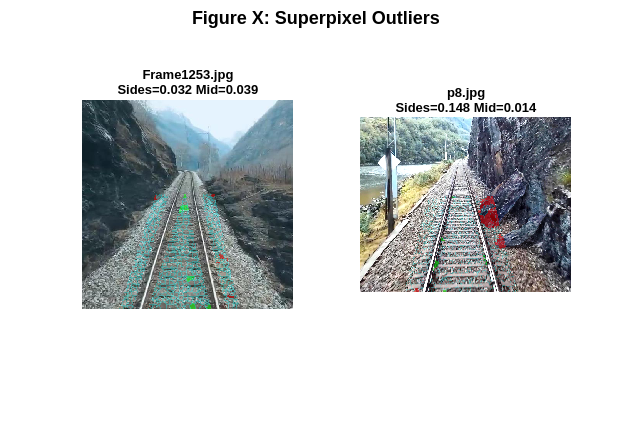

figure('Name', 'Edge Detection on Gaussian and Unsharp Masking', ...
       'NumberTitle', 'off', ...
       'Position', [0, 0, 6*200, length(SELECTED)*200]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);

    img_g = images_gauss{i};
    us  = images_us{i};

    % Gaussian edges
    img_g_prewitt = edge(img_g, 'prewitt');

    img_g_sobel   = edge(img_g, 'sobel');
    img_g_canny   = edge(img_g, 'canny');

    % Unsharp edges 
    e_us_prewitt  = edge(us, 'prewitt');
    e_us_sobel    = edge(us, 'sobel');
    e_us_canny    = edge(us, 'canny');

    base = (row_disp-1)*6;

    subplot(length(SELECTED), 6, base + 1);
    imshow(img_g_prewitt);
    title('Gaussian Prewitt', 'FontSize', 7);

    subplot(length(SELECTED), 6, base + 2);
    imshow(img_g_sobel);
    title('Gaussian Sobel', 'FontSize', 7);

    subplot(length(SELECTED), 6, base + 3);
    imshow(img_g_canny);
    title('Gaussian Canny', 'FontSize', 7);

    subplot(length(SELECTED), 6, base + 4);
    imshow(e_us_prewitt);
    title('Unsharp Prewitt', 'FontSize', 7);

    subplot(length(SELECTED), 6, base + 5);
    imshow(e_us_sobel);
    title('Unsharp Sobel', 'FontSize', 7);

    subplot(length(SELECTED), 6, base + 6);
    imshow(e_us_canny);
    title('Unsharp Canny', 'FontSize', 7);
end

sgtitle('Edge Detection (Prewitt / Sobel / Canny) on Gaussian and Unsharp Masking', ...

    Image         Filename         InitialClass    SidesRatio    MiddleRatio     FinalClass 
    _____    __________________    ____________    __________    ___________    ____________

      2      {'Frame1253.jpg' }      "Clear"        0.032284       0.039112     "Clear"     
      3      {'Frame1291.jpg' }      "Clear"        0.025374     0.00021322     "Clear"     
      4      {'Frame1532.jpg' }      "Clear"         0.04697       0.068593     "Clear"     
      5      {'Frame1603.jpg' }      "Clear"        0.011029       0.030247     "Clear"     
      7      {'image00756.jpg'}      "Clear"               0       0.047481     "Clear"     
      8      {'image02293.jpg'}      "Clear"         0.02006       0.015728     "Clear"     
     10      {'image04925.jpg'}      "Clear"       

        'FontSize', 12, 'FontWeight', 'bold');

While these edge detectors effectively highlighted edges visually, their outputs were often fragmented, contained noise, or included irrelevant background structures. Such inconsistencies make it difficult to automatically extract continuous rail lines across the entire image.

### 1.5. Otsu's Method

In order to explore alternative approaches, and given that DoG already emphasizes rail edges while suppressing background noise, Otsu’s thresholding was considered as a complementary method. Otsu automatically determines an intensity threshold to binarize the image, separating foreground structures (rails) from the background. This approach is particularly useful in our case because the DoG-enhanced images already present clear rail patterns, allowing Otsu to produce continuous, clean binary masks that are more suitable for line extraction and subsequent Hough transform analysis, without requiring explicit gradient computation.

images_otsu_dog = cell(N, 1);

for i = 1:N
    level = graythresh(images_dog{i});
    bw    = imbinarize(images_dog{i}, level);
    images_otsu_dog{i} = bwareaopen(bw, 50);
end

figure('Name', 'Otsu on DoG', ...
       'NumberTitle', 'off', ...
       'Position', [0, 0, 2*200, length(SELECTED)*200]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);

    subplot(length(SELECTED), 2, (row_disp-1)*2 + 1);
    imshow(images_dog{i});
    title('DoG', 'FontSize', 8);

    subplot(length(SELECTED), 2, (row_disp-1)*2 + 2);
    imshow(images_otsu_dog{i});
    title('Otsu(DoG)', 'FontSize', 8);
end


    Image         Filename         InitialClass     FinalClass      TrueClass  
    _____    __________________    ____________    ____________    ____________

      1      {'cortada11.png' }    "Obstructed"    "Obstructed"    "Obstructed"
      2      {'Frame1253.jpg' }    "Clear"         "Clear"         "Clear"     
      3      {'Frame1291.jpg' }    "Clear"         "Clear"         "Clear"     
      4      {'Frame1532.jpg' }    "Clear"         "Clear"         "Clear"     
      5      {'Frame1603.jpg' }    "Clear"         "Clear"         "Clear"     
      6      {'Frame1616.jpg' }    "Obstructed"    "Obstructed"    "Obstructed"
      7      {'image00756.jpg'}    "Clear"         "Clear"         "Clear"     
      8      {'image02293.jpg'}    "Clear"         "Clear"         "Clear"     
      9      {'image04054.jpg

sgtitle('Otsu Thresholding on DoG', ...
        'FontSize', 12, 'FontWeight', 'bold');

As shown in the results, applying Otsu's thresholding directly to the DoG enhanced images produced clean binary masks in which the rail structures appear as continuous white contours against a dark background. Compared to the gradient-based edge detectors, which frequently yielded fragmented edges and residual noise from surrounding vegetation and terrain, the Otsu(DoG) output preserves the overall rail geometry more consistently across the selected images. The binarized images retain the dominant structural lines while suppressing low-contrast background regions, making them more robust as input for the subsequent Hough transform step. 

Based on these observations, Otsu thresholding applied to the DoG-enhanced images was selected as the preferred binarization strategy for the remainder of the pipeline.

### 1.5. Region of Interest (ROI)

In railway images, not all areas of the frame are relevant for line detection. Background structures, shadows or vegetation, can introduce noise and lead to false detections. To mitigate these disturbances, a Region of Interest (ROI) is defined that focuses processing on the portion of the image containing the railway track.

We chose a trapezoidal ROI because the track converges towards the horizon due to perspective. This configuration ensures that most of the visible track is included while ignoring regions that may produce disturbances. 

The ROI is defined as fractions of the image size, with the following parameters:

- Bottom-left (BL): 5% of image width

- Bottom-right (BR): 95% of image width

- Top-left (TL): 30% of image width

- Top-right (TR): 70% of image width

- Top boundary (Y): 45% of image height

However, defining the ROI is a trade-off. A larger ROI may capture more of the track but also includes more background noise, potentially reducing the accuracy of line detection. Conversely, a smaller ROI reduces noise but risks cutting off relevant track information.

In the implementation, a binary mask is generated from these ROI coordinates and applied to the Otsu(DoG) images. This results in a focused binary representation of the railway track.

% ROI Parameters
ROI_BL_X = 0.05;   % bottom-left
ROI_BR_X = 0.95;   % bottom-right
ROI_TL_X = 0.30;   % top-left
ROI_TR_X = 0.70;   % top-right
ROI_TOP_Y = 0.45;   % top y fraction

% Apply ROI TO Otsu(DoG) IMAGES

PRECISION (Obstructed): 1.00  (TP=7, FP=0)


images_otsu_dog_roi = cell(N,1);

for i = 1:N
    bw = images_otsu_dog{i};
    [h,w] = size(bw);
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h,h,ROI_TOP_Y*h,ROI_TOP_Y*h];
    mask = poly2mask(roi_x,roi_y,h,w);
    images_otsu_dog_roi{i} = bw .* mask;
end

% Original RGB and Otsu(DoG) with ROI
figure('Name','Original and Otsu(DoG) with ROI','NumberTitle','off','Position',[0 0 800 600]);

for k = 1:length(SELECTED)
    i = SELECTED(k);
    rgb_img = images{i};        
    bw_roi  = images_otsu_dog_roi{i};  

    [h,w] = size(bw_roi);
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h,h,ROI_TOP_Y*h,ROI_TOP_Y*h];

    % Original RGB with ROI
    subplot(length(SELECTED),2,(k-1)*2 + 1);
    imshow(rgb_img);
    hold on;
    plot([roi_x roi_x(1)], [roi_y roi_y(1)], 'r-', 'LineWidth', 1.5);
    hold off;
    title(sprintf('Original RGB with ROI'),'FontSize',10);

    % Otsu(DoG) with ROI 
    subplot(length(SELECTED),2,(k-1)*2 + 2);
    imshow(bw_roi);
    hold on;
    plot([roi_x roi_x(1)], [roi_y roi_y(1)], 'r-', 'LineWidth', 1.5);
    hold off;
    title(sprintf('Otsu(DoG) with ROI [%d]', i),'FontSize',10);
end

sgtitle('Original RGB and Otsu(DoG) with ROI','FontSize',12,'FontWeight','bold');

In the previous figures, the respective ROI is applied to the selected images, allowing validation that the ROI captures the track without hiding important details.

### 1.6. Morphological Operations

After ROI application, the next step in the pipeline is morphological processing, whose main objective is to clean the binary images and remove small artifacts while preserving the relevant rail edges. Despite the ROI focusing on the track area, the Otsu(DoG) images still contain small isolated pixels and noise that can interfere with line detection and Hough transform analysis.

To evaluate the most suitable approach, three morphological operations were tested on a representative subset of five images:

- bwareaopen 

- imopen

- imclose

Bwareaopen removes objects below a certain size, excluding scattered noise while preserving the main track structure. Imopen combines erosion and dilation, smoothing edges and removing small protrusions or thin connections. Imclose, on the other hand, fills small gaps or holes in the structures, making the rail lines more continuous. 

The disk-shaped structuring element with radius 3 was chosen to ensure isotropic cleaning around the edges, which suits the irregular small noise in the binary masks.

The bwareaopen threshold of 100 pixels was determined empirically by testing several images.

min_pixels = 100;          % bwareaopen threshold
strel_radius = 3;          % imopen/imclose radius
se = strel('disk', strel_radius);

images_bwarea = cell(N,1);
images_open   = cell(N,1);
images_close  = cell(N,1);

% Apply morphological operations
for i = 1:N
    bw = images_otsu_dog{i};
    [h, w] = size(bw);

    % ROI mask
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    mask = poly2mask(roi_x, roi_y, h, w);

    bw_roi = bw & mask;

    % Morphological operations
    bw_bwarea = bwareaopen(bw_roi, min_pixels);
    bw_open   = imopen(bw_roi, se);
    bw_close  = imclose(bw_roi, se);

    images_bwarea{i} = bw_bwarea;
    images_open{i}   = bw_open;
    images_close{i}  = bw_close;
end

figure('Name','Morphological Operations on Selected Images','NumberTitle','off', ...
       'Position',[0 0 1800 900]);

for row = 1:length(SELECTED)
    i = SELECTED(row);
    bw = images_otsu_dog{i};
    [h, w] = size(bw);

    % ROI mask
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    mask = poly2mask(roi_x, roi_y, h, w);
    bw_roi = bw & mask;

    bw_bwarea = images_bwarea{i};
    bw_open   = images_open{i};
    bw_close  = images_close{i};

    subplot(length(SELECTED),4,(row-1)*4 + 1);
    imshow(bw_roi);
    title('Otsu(DoG)','FontSize',10);

    subplot(length(SELECTED),4,(row-1)*4 + 2);
    imshow(bw_bwarea);
    title('bwareaopen','FontSize',10);

    subplot(length(SELECTED),4,(row-1)*4 + 3);
    imshow(bw_open);
    title('imopen','FontSize',10);

    subplot(length(SELECTED),4,(row-1)*4 + 4);
    imshow(bw_close);
    title('imclose','FontSize',10);
end

sgtitle('Morphological Operations on Otsu(DoG)','FontSize',12,'FontWeight','bold');

As observed in the results, the three morphological operations produced markedly different outcomes. The `imopen` operation was too aggressive for this application, in all three images it nearly completely erased the binary content. This indicates that the disk structuring element with radius 3 is too large relative to the thin rail edge structures present in the Otsu(DoG) output. `imclose`, while preserving more structure and successfully filling small gaps along the rail lines, also introduced unwanted background regions and thickened irrelevant contours, making the output noisier than the original. `bwareaopen`, in contrast, consistently retained the dominant rail structures across all three images while removing small isolated blobs, without altering the geometry or connectivity of the main edges. 

Based on these observations, `bwareaopen` with a threshold of 100 pixels was selected as the morphological cleaning strategy for the remainder of the pipeline, as it offers the best balance between noise removal and structural preservation.

### 1.7. Hough Transform

After morphological processing, the next step in the pipeline is line detection using the Hough Transform. The goal of this stage is to identify the dominant linear structures corresponding to the railway tracks in the cleaned binary images. The Hough Transform maps points from the image space into a parameter space defined by ρ and θ, where peaks represent potential lines. For each processed image, the transform is computed and the two strongest peaks are selected, as they typically correspond to the left and right edges. A threshold of 30% of the maximum accumulator value is used to filter out weaker detections and reduce noise influence. The corresponding lines are then extracted using a minimum length constraint and a small gap-filling parameter to ensure continuity.

figure('Name','Hough Transform Lines','NumberTitle','off','Position',[0 0 2000 1200]);

cols = 5;
rows = ceil(N / cols);

for i = 1:N
    bw_clean = images_bwarea{i};

    % Compute Hough Transform
    [H, theta, rho] = hough(bw_clean);

    % Find two strongest peaks in Hough space
    P = houghpeaks(H, 2, 'Threshold', ceil(0.3*max(H(:))));

    % Extract lines corresponding to these peaks
    lines = houghlines(bw_clean, theta, rho, P, 'FillGap', 10, 'MinLength', 50);

    subplot(rows, cols, i);
    imshow(bw_clean); hold on;

    % Overlay detected lines in green
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    end

    title(sprintf('[%d]', i),'FontSize',8);
    hold off;
end

sgtitle('Hough Transform Lines','FontSize',12,'FontWeight','bold');

The Hough transform was applied to all 15 binary images, detecting up to two dominant lines per image. While the algorithm successfully identified rail-like structures in several images, a number of limitations are evident. In some cases, the detected lines do not correspond to the actual railway edges, instead latching onto irrelevant structures within the ROI. In others, only one line is detected or both detected lines are nearly coincident, failing to represent the two distinct rail edges. Additionally, some images contain curved tracks, for which a straight-line Hough model is inherently limited, the detected segment only fits a portion of the rail, leaving the remaining curvature unrepresented. These observations motivate a refinement step to improve the reliability and accuracy of rail line detection across the full dataset.

#### 1.7.1. Angle and Distance Filtering

To address the limitations identified in the initial Hough detection, three refinement constraints were introduced. Angular filter restricting detected lines to the range θ ∈ [−50°, 50°], eliminating near-horizontal detections that typically correspond to sleepers or obstructions rather than rail edges. Increased peak search from 2 to 12 candidates, providing a larger pool of lines to select from, and a minimum horizontal separation threshold of 20 pixels between selected lines, preventing the selection of two nearly coincident lines representing the same rail edge. The `FillGap` and `MinLength` parameters control segment merging and minimum length respectively, ensuring that only sufficiently long and continuous line segments are retained after the Hough transform.

figure('Name','Hough Transform Lines Refined','NumberTitle','off',...
       'Position',[0 0 2000 1200]);

% Parameters
theta_min = -50;
theta_max = -theta_min;
x_thresh  = 20;   % minimum horizontal distance

for i = 1:N
    bw_clean = images_bwarea{i};

    % Hough Transform
    [H, theta, rho] = hough(bw_clean);

    % More peaks
    P = houghpeaks(H, 12, 'Threshold', ceil(0.3*max(H(:))));

    % Extract candidate lines
    lines = houghlines(bw_clean, theta, rho, P, ...
                       'FillGap', 10, 'MinLength', 50);

    % Filter by angle
    lines_theta = lines([lines.theta] >= theta_min & ...
                        [lines.theta] <= theta_max);

    % Select separated lines
    selected_lines = [];

    if ~isempty(lines_theta)
        % Sort by length
        lengths = arrayfun(@(l) norm(l.point1 - l.point2), lines_theta);
        [~, idx] = sort(lengths, 'descend');

        for k = 1:numel(idx)
            l = lines_theta(idx(k));
            x_mean = mean([l.point1(1), l.point2(1)]);

            keep = true;
            for sl = selected_lines
                x_sel = mean([sl.point1(1), sl.point2(1)]);
                if abs(x_mean - x_sel) < x_thresh
                    keep = false;
                    break;
                end
            end

            if keep
                selected_lines = [selected_lines, l];
            end

            % keep only top 2 lines
            if numel(selected_lines) >= 2
                break;
            end
        end
    end

    subplot(rows, cols, i);
    imshow(bw_clean); hold on;

    for k = 1:length(selected_lines)
        xy = [selected_lines(k).point1; selected_lines(k).point2];
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    end

    title(sprintf('[%d]', i),'FontSize',8);
    hold off;
end

sgtitle('Hough Transform Lines with Angle and Distance Filtering',...
        'FontSize',12,'FontWeight','bold');

As visible in the refined results, the detection improved considerably across the majority of images. The characteristic converging V-shape of the rails is now correctly identified in several images, where both lines are well separated and angularly consistent with the expected rail geometry. Nevertheless, several cases still present difficulties, some images show only partial line segments that do not span the full extent of the rail, and images containing curved tracks remain particularly challenging, as the Hough transform is inherently limited to straight-line detection and can only fit a segment to the locally dominant orientation of the curve. These remaining failures indicate that further refinement is still needed to achieve robust and consistent rail detection across the full dataset.

#### 1.7.2. Hough Transform Lines with ROI Strips

To further improve detection consistency, the ROI was divided into 3 horizontal strips of equal height, and the Hough transform was applied independently to each strip. This strip-based approach allows the algorithm to detect rail lines at different depths within the scene, bottom strips correspond to the near track where rails are wider apart, while upper strips capture the vanishing point region where rails converge. Furthermore, by fitting independent line segments at each vertical level, this approach also better accommodates curved tracks, where a single global line would fail to capture the changing orientation of the rail. Each strip is processed with the same angular and horizontal separation filters as before, selecting up to 2 lines per strip. The detected lines are colour-coded by strip, green, cyan, and yellow from bottom to top, allowing visual assessment of detection continuity along the full rail extent.

figure('Name','Hough Transform Lines with ROI Strips','NumberTitle','off',...
       'Position',[0 0 2000 1200]);
n_strips  = 3;

colors = {'g','c','y'};

for i = 1:N
    bw_clean = images_bwarea{i};
    [h, w] = size(bw_clean);

    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];

    y_top = ROI_TOP_Y*h;
    y_bottom = h;
    strip_height = (y_bottom - y_top)/n_strips;

    subplot(rows, cols, i);
    imshow(bw_clean); hold on;

    plot([roi_x roi_x(1)], [roi_y roi_y(1)], 'r-', 'LineWidth', 1.5);

    for s = 1:n_strips
        y_start = round(y_top + (s-1)*strip_height);
        y_end   = round(y_top + s*strip_height);

        % Strip mask
        strip_mask = false(h,w);
        strip_mask(y_start:y_end, :) = true;

        bw_strip = bw_clean & strip_mask;

        % Hough
        [H,theta,rho] = hough(bw_strip);
        P = houghpeaks(H, 12, 'Threshold', ceil(0.3*max(H(:))));
        lines = houghlines(bw_strip, theta, rho, P,...
                           'FillGap', 5, 'MinLength', 20);

        % Angle filtering
        lines_theta = lines([lines.theta] >= theta_min & ...
                            [lines.theta] <= theta_max);

        selected_lines = [];

        if ~isempty(lines_theta)
            lengths = arrayfun(@(l) norm(l.point1 - l.point2), lines_theta);
            [~, idx] = sort(lengths, 'descend');

            for k = 1:numel(idx)
                l = lines_theta(idx(k));
                x_mean = mean([l.point1(1), l.point2(1)]);

                keep = true;
                for sl = selected_lines
                    x_sel = mean([sl.point1(1), sl.point2(1)]);
                    if abs(x_mean - x_sel) < x_thresh
                        keep = false;
                        break;
                    end
                end

                if keep
                    selected_lines = [selected_lines, l];
                end

                if numel(selected_lines) >= 2
                    break;
                end
            end
        end

        % Plot lines per strip
        for k = 1:length(selected_lines)
            xy = [selected_lines(k).point1; selected_lines(k).point2];
            plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', colors{s});
        end
    end

    title(sprintf('[%d]', i),'FontSize',8);
    hold off;
end

sgtitle('Hough Lines per ROI Strip','FontSize',12,'FontWeight','bold');

As observed in the results, the strip-based approach yielded a notable improvement in rail detection across the dataset. In the majority of images, particularly [2], [3], [4], [5], [8], [10], [11], and [15] all three strips successfully detected two well-separated lines per level, with the colour-coded segments forming a coherent and continuous rail structure from the bottom of the ROI up to the vanishing point. The progressive narrowing of the detected line pairs from yellow to cyan to green visually confirms that the perspective geometry of the track is being correctly captured at each depth level. For curved track images such as [9] and [11], the independent per-strip fitting allows the detected segments to follow the changing rail orientation across strips, something that a single global line would be unable to achieve. Overall, the strip-based refinement significantly increased detection coverage and spatial consistency compared to the global Hough approach.

### 1.8. Final Line Detection Pipeline

After evaluating the different preprocessing, filtering, and detection strategies, a final pipeline was established to achieve robust and consistent railway track detection. This pipeline combines the most effective steps identified previously, including noise reduction, region of interest (ROI) selection, and morphological processing, resulting in clean binary images suitable for line extraction.

Although contrast enhancement using CLAHE was initially considered, experimental results showed that its inclusion in the final detection stage led to poorer performance, mainly due to the amplification of noise and non-relevant structures. Therefore, CLAHE was not included in the final pipeline.

The Hough Transform is then applied with additional constraints on line orientation and spatial separation to ensure that only relevant rail candidates are retained. To further improve robustness, the detection is performed using a strip-based approach within the ROI, allowing the method to adapt to local variations along the track and remain resilient to noise, shadows, and partial occlusions.

Finally, to obtain a coherent representation of the railway geometry, the detected line segments are processed from bottom to top and combined using smooth interpolation. This produces continuous and stable rail boundaries.

% Parameters
min_pixels = 100;
theta_min = -50; 
theta_max = 50;
x_thresh = 20;
n_strips = 3;

ROI_BL_X = 0.05; ROI_BR_X = 0.95;
ROI_TL_X = 0.3;  ROI_TR_X = 0.7;
ROI_TOP_Y = 0.45;

cols = 5;
rows = ceil(N/cols);

% Preprocessing: DoG + Otsu + Cleaning
images_otsu_dog = cell(N,1);

for i = 1:N
    img = imread(filenames{i});
    if size(img,3)==3
        img = rgb2gray(img);
    end

    g1 = imgaussfilt(img,1);
    g2 = imgaussfilt(img,2);
    dog = imsubtract(g1,g2);

    level = graythresh(dog);
    bw = imbinarize(dog,level);

    bw = bwareaopen(bw,min_pixels);
    images_otsu_dog{i} = bw;
end

% Process each image
figure('Name','Optimized Smooth Lines','NumberTitle','off',...
       'Position',[0 0 2200 1200]);

for i = 1:N
    img_orig = imread(filenames{i});
    if size(img_orig,3)==1
        img_orig = repmat(img_orig,[1 1 3]);
    end

    bw = images_otsu_dog{i};
    [h,w] = size(bw);

    % ROI
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    mask = poly2mask(roi_x,roi_y,h,w);
    bw_roi = bw & mask;

    % Strip setup
    y_top = ROI_TOP_Y*h;
    y_bottom = h;
    strip_height = (y_bottom - y_top)/n_strips;

    left_segments = {};
    right_segments = {};

    % Process strips (bottom to top)
    for s = n_strips:-1:1
        y_start = round(y_top + (s-1)*strip_height);
        y_end   = round(y_top + s*strip_height);

        strip_mask = false(h,w);
        strip_mask(y_start:y_end,:) = true;
        bw_strip = bw_roi & strip_mask;

        % Hough Transform
        [H,theta,rho] = hough(bw_strip);
        P = houghpeaks(H,12,'Threshold',ceil(0.3*max(H(:))));
        lines = houghlines(bw_strip,theta,rho,P,...
                           'FillGap',10,'MinLength',50);

        % Angle filtering
        lines_theta = lines([lines.theta]>=theta_min & ...
                            [lines.theta]<=theta_max);

        if isempty(lines_theta)
            break
        end

        % Select up to 2 dominant lines
        lengths = arrayfun(@(l) norm(l.point1-l.point2), lines_theta);
        [~, idx] = sort(lengths,'descend');

        selected_lines = [];

        for k = 1:numel(idx)
            l = lines_theta(idx(k));
            x_mean = mean([l.point1(1),l.point2(1)]);

            keep = true;
            for sl = selected_lines
                x_sel = mean([sl.point1(1),sl.point2(1)]);
                if abs(x_mean - x_sel)<x_thresh
                    keep=false; break;
                end
            end

            if keep
                selected_lines = [selected_lines,l];
            end

            if numel(selected_lines)>=2
                break;
            end
        end

        % Separate left/right
        if ~isempty(selected_lines)
            x_means = arrayfun(@(l) mean([l.point1(1),l.point2(1)]), selected_lines);
            [~, idx_left] = min(x_means);
            [~, idx_right] = max(x_means);

            left_segments{end+1}  = [selected_lines(idx_left).point1;
                                    selected_lines(idx_left).point2];

            right_segments{end+1} = [selected_lines(idx_right).point1;
                                    selected_lines(idx_right).point2];
        end
    end

    subplot(rows,cols,i); 
    imshow(img_orig); hold on;

    plot([roi_x roi_x(1)],[roi_y roi_y(1)],'r-','LineWidth',1.5);

    plot_segments(left_segments);
    plot_segments(right_segments);

    title(sprintf('[%d]',i),'FontSize',8);
    hold off;
end

sgtitle('Smooth Continuous Rail Lines (Strip-Based)','FontSize',12,'FontWeight','bold');

As observed in the final results, the complete pipeline produces a notably more coherent and visually accurate rail detection across the dataset. The spline interpolation across strips effectively connects the per-strip detections into continuous curves, which is especially beneficial for images with curved tracks such as [11] and [12], where the lines adapt to the changing rail orientation rather than forcing a single straight fit. Image [9] also shows a reasonable detection despite the presence of scattered noise from the surrounding terrain. 

Overall, the final pipeline demonstrates a clear improvement over all previous stages, successfully detecting and representing the railway geometry.

### 1.9. Ground Truth Comparison

To evaluate the performance of our railway inspection pipeline, we first manually created a ground truth dataset of rail positions. Each image was loaded, and the we manually selected points along the left and right rails. Points were recorded and this procedure produced a precise set of coordinates for all visible rails, saved in the `ground_truth.mat` file.

With this ground truth dataset established, we can now visually compare the manually annotated rails to the rail lines detected automatically by our pipeline algorithm. For each image, the ground truth rails are plotted in blue. This allows an immediate and intuitive visual assessment of how closely the automated pipeline matches the manually annotated ground truth.

% Load ground truth
load('./Data/ground_truth.mat');  

figure('Name', 'Ground Truth Rail Annotations', ...
       'NumberTitle', 'off', 'Position', [0 0 1600 950]);

for i = 1:N
    imgRGB = imread(filenames{i});
    subplot(3,5,i);
    
    plotGroundTruth(imgRGB, gt(i));
    
    nL = size(gt(i).left,  1);
    nR = size(gt(i).right, 1);
    
    title(sprintf('[%d] %s\nL:%d pts  R:%d pts', i, gt(i).filename, nL, nR), ...
        'FontSize', 7, 'Interpreter', 'none');
end

sgtitle('Ground Truth Manual Rail Annotations', ...
        'FontSize', 13, 'FontWeight', 'bold');

Observing the results, it is evident that the automatically obtained smooth continuous rail lines closely match the manually annotated ground truth. Both the left and right rails detected by the pipeline align very well with the ground truth points, demonstrating that the strip-based Hough transform and line-fitting method is effective in reproducing the true rail geometry. 

This visual comparison confirms the reliability and accuracy of the automatic detection pipeline, providing confidence that it can be used for large-scale railway inspection tasks with minimal manual intervention.

While for this small dataset a quantitative measure such as Mean Squared Error (MSE) between ground truth and detected lines is not strictly necessary, for larger datasets it would be a valuable metric to tune algorithm parameters and systematically evaluate performance. This suggests that, in future work, incorporating such measures could help optimize detection thresholds, improve robustness, and provide an objective comparison across different inspection conditions.

## 3. Detection of Objects in Side and Inter-Rail Regions

The track detection methodology was robust and reliably detected obstructions on the rails. However, it did not detect obstructions along the sides of the track or in the inter-rail region. In the first iteration, the only misclassification was image p8.jpg: the rails appear clear, but large boulders on the right side of the image would obstruct the passage of a train, as they are very close to the track. Such obstructions could indirectly cause a derailment. The image is once again visualized:

% Run checkpoint 
aux_checkpoint

% Define the image file name
filename = 'p8.jpg'; 
folder = fullfile(pwd, 'Data'); 
filepath = fullfile(folder, filename);

% Load the image
img = imread(filepath);

% Display the image
imshow(img);

% Add title
title({'Image X: Outlier classified as Clear'}, 'FontSize', 10);

To address this limitation, we added an extra validation stage for images initially classified as clear, as described in the following steps:

- Rail regression

- Three-way region split

- Superpixel segmentation and Outlier detection

- Anomaly ratio for classification

### 3.1 Rail Regression

Rail regression fits smooth curves to the left and right rails, enabling the subsequent definition of side and inter-rail regions for obstruction detection. The algorithm takes as input the preprocessed binary image obtained in the previous section. 

The endpoints of the extracted line segments are collected for each rail, forming two distinct point sets: one corresponding to the left rail and one to the right rail. A degree-2 polynomial is then fitted to each set using least-squares regression, modeling the rail's horizontal position as a function of the image row. The model takes the form:


$$x = p_1 y^2 + p_2 y + p_3$$


where $x
$ represents the horizontal coordinate, $y$ the row index, and $p_1, p_2, p_3$ the polynomial coefficients obtained via standard polynomial fitting techniques such as MATLAB's `polyfit` function.

The choice of a quadratic model is motivated by the perspective distortion present in railway images. Railway tracks appear to converge toward the horizon and may exhibit slight curvature, characteristics that a degree-2 polynomial captures more accurately than a simple linear model, while remaining computationally efficient and robust to noise. The output of this regression stage consists of the fitted polynomials, which define the left and right rail positions for any given row $y
$ within the image serving as the foundation for the subsequent analysis stage. The results for 2 images can be seen in Figure X where the left rail regression polynomial is in yellow and the right rail regression polynomial is in blue.

clear_idx = find(predicted_status == "Clear");

for k = 1:numel(clear_idx)
    i = clear_idx(k);
    
    % Get preprocessed binary image for this image
    bw_clean = images_otsu_dog_roi_clean{i};
    [h, w] = size(bw_clean);
    
    % Build ROI mask (trapezoid)
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    roi_mask = poly2mask(roi_x, roi_y, h, w);
    
    % Call your auxiliary function
    [left_pts, right_pts, left_segments, right_segments, ...
     x_left_fit, x_right_fit, y_fit, p_left, p_right] = ...
        aux_rail_regression(bw_clean, roi_mask, n_strips, ...
        theta_min, theta_max, x_thresh);
    
    % Use outputs (e.g. store for later steps)
    rail_fits{i} = struct('left_pts', left_pts, 'right_pts', right_pts, ...
        'left_segments', {left_segments}, 'right_segments', {right_segments}, ...
        'x_left_fit', x_left_fit, 'x_right_fit', x_right_fit, ...
        'y_fit', y_fit, 'p_left', p_left, 'p_right', p_right, ...
        'roi_x', roi_x, 'roi_y', roi_y);
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.rail_fits = rail_fits;
results.filenames = filenames;

% Plot rail regression for clear images 1 and 2 only
plot_rail_regression(results, images, [1, 9]);

### 3.2 Three-way region split

The three-way region split utilizes the fitted rail polynomials from the previous regression step to define three distinct regions of interest: left, middle, and right. These regions serve as the basis for subsequent superpixel-based anomaly detection, enabling targeted analysis of areas relevant to railway obstruction identification.

The function receives as input the image dimensions, the polynomial coefficients for the left and right rails, and three parameters: `ROI_TOP_Y`, `rail_padding`, and `pct_side`. After generating rail position maps, where for each row the horizontal positions of the left and right rails are computed using the fitted polynomials, a vertical mask is then applied to exclude the upper portion of the image, just like in the initial region of interest.

Since the rail trajectories are now known, we can take advantage of this information by creating an adaptive ROI that follows the track, rather than using a hardcoded region. This is achieved by defining a percentage of the image width to extend outward from each rail, specified by the parameter `pct_side`. The value of `pct_side` was empirically chosen as 10% based on preliminary observations. Additionally, the mask excludes a empirically chosen 20-pixel width corresponding to the rails themselves, under the assumption that the track area of interest lies adjacent to, rather than on, the rails.

The output of this stage consists of three logical masks, each of size $h\times w$, indicating the pixels belonging to the left, middle, and right regions, respectively. These masks are subsequently used to constrain superpixel analysis to each region independently, improving detection accuracy by focusing on region-specific characteristics. The results for 2 images can be seen in Figure X where the left section is masked with red, the middle with green and the right with blue.

clear_idx = find(predicted_status == "Clear");

% Parameters
rail_padding = 20;
pct_side = 0.10;

N = length(images);
region_left   = cell(N, 1);
region_middle = cell(N, 1);
region_right  = cell(N, 1);

for k = 1:numel(clear_idx)
    i = clear_idx(k);

    [h, w, ~] = size(images{i});
    rf = rail_fits{i};
    p_left = rf.p_left;
    p_right = rf.p_right;

    [left_region, mid_region, right_region] = aux_three_way_regions(h, w, ...
        p_left, p_right, ROI_TOP_Y, rail_padding, pct_side);

    region_left{i}   = left_region;
    region_middle{i} = mid_region;
    region_right{i}  = right_region;
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.region_left   = region_left;
results.region_middle  = region_middle;
results.region_right  = region_right;
results.filenames = filenames;
results.roi_params = struct('pct_side', pct_side, 'rail_padding', rail_padding);

% Plot 3-way regions for clear 2 images
plot_three_way_regions(results, images, [8, 9]);

### 3.3 Superpixel segmentation and Outlier detection

The image is then converted to the LAB color space and segmented using the SLIC algorithm. Segmentation is performed on the full image to ensure that superpixel boundaries follow natural edges corresponding to objects, ballast, and other scene elements. The number of superpixels was set to 2500, a value that was empirically determined to provide the best trade-off between region size and computational performance. The SLIC compactness parameter was set to 10; lower compactness values yield more irregular boundaries that better adhere to object contours, which is desirable for accurately delineating potential obstacles.

For each superpixel that overlaps with one of the three regions of interest, a 6D feature vector is computed in LAB space, consisting of the median and standard deviation of the L, a, and b channels. This combination captures both color information and local texture characteristics. Features are computed exclusively from pixels lying within each region mask to ensure region-specific analysis.

The median was chosen over the mean for the central tendency measure because it is inherently more robust to outliers. Since the goal of this stage is precisely to detect anomalous objects that differ from the surrounding environment, using the mean would allow those same anomalies to skew the feature representation, potentially masking their presence.

Superpixel features from the left and right regions are pooled together, under the assumption that both sides consist of similar ground material. The median and interquartile range (IQR) are computed for each of the six feature dimensions across the pooled set. Each superpixel's feature vector is then normalized by subtracting the median and dividing by the IQR. The Euclidean distance of this normalized vector from the origin serves as the outlier score. Superpixels with a distance exceeding the Tukey fence defined as $Q3+1.5\times IQR$ are flagged as anomalous. The same process is done on the middle section.

For both the side regions and the middle region, an anomaly ratio is computed as the fraction of pixels belonging to anomalous superpixels relative to the total number of pixels in that region. These ratios are subsequently used in the final classification step to determine the presence of obstructions. The results for 2 images can be seen in Figure where the outlier superpixels are coloured red on the side sections and green in the middle sections.

clear_idx = find(predicted_status == "Clear");

num_superpixels = 2500;
sp_compactness  = 10;
iqr_multiplier  = 1.5;

N = length(images);
anomaly_maps   = cell(N, 3);
anomaly_ratios = nan(N, 2);
sp_labels_all  = cell(N, 3);

for k = 1:numel(clear_idx)
    i = clear_idx(k);
    img = images{i};
    if size(img, 3) == 1
        img = repmat(img, [1 1 3]);
    end

    [anom_left, anom_mid, anom_right, sp_labels, r_sides, r_mid] = ...
        aux_superpixel_and_outliers(img, region_left{i}, region_middle{i}, region_right{i}, ...
        num_superpixels, sp_compactness, iqr_multiplier);

    anomaly_maps{i, 1} = anom_left;
    anomaly_maps{i, 2} = anom_mid;
    anomaly_maps{i, 3} = anom_right;
    anomaly_ratios(i, 1) = r_sides;
    anomaly_ratios(i, 2) = r_mid;
    sp_labels_all{i, 1} = sp_labels{1};
    sp_labels_all{i, 2} = sp_labels{2};
    sp_labels_all{i, 3} = sp_labels{3};
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.region_left   = region_left;
results.region_middle = region_middle;
results.region_right  = region_right;
results.anomaly_maps  = anomaly_maps;
results.anomaly_ratios = anomaly_ratios;
results.sp_labels_all = sp_labels_all;
results.filenames = filenames;
results.sp_params = struct('num_superpixels', num_superpixels, 'iqr_multiplier', iqr_multiplier);

% Plot superpixel outliers for clear images 1 and 8
plot_superpixel_outliers(results, images, [1, 9]);

### 3.4 Anomaly ratio for classification

This constitutes the final step of the secondary classification pipeline. It is important to recall that this stage is applied exclusively to images that were initially classified as "Clear", meaning that the tracks were successfully extracted by the first classification algorithm. This step examines the anomaly ratios computed for the side and middle regions. 

If the percentage of anomalous superpixels in either region exceeds 10%, the image is reclassified as "Obstructed". This threshold was deemed sufficient based on empirical observation. Thus, the anomaly ratios effectively indicate the presence of obstructions in the side or inter-rail regions that were not detected by the first-stage Hough-based method.

clear_idx = find(predicted_status == "Clear");

anomaly_percentage_thresh = 0.1;

final_status = aux_anomaly_classification(predicted_status, anomaly_ratios, anomaly_percentage_thresh);

% Build minimal results struct (for consistency; no plot for step 4)
results.clear_idx = clear_idx;
results.final_status = final_status;
results.anomaly_ratios = anomaly_ratios;
results.filenames = filenames;

% Final summary table (only images initially classified as Clear)
nClear = numel(clear_idx);
img_names_clear = cell(nClear, 1);
for k = 1:nClear
    i = clear_idx(k);
    [~, fname, ext] = fileparts(filenames{i});
    img_names_clear{k} = [fname ext];
end

final_summary = table(...
    clear_idx(:), ...
    img_names_clear, ...
    predicted_status(clear_idx(:)), ...
    anomaly_ratios(clear_idx(:), 1), ...
    anomaly_ratios(clear_idx(:), 2), ...
    final_status(clear_idx(:)), ...
    'VariableNames', {'Image', 'Filename', 'InitialClass', 'SidesRatio', 'MiddleRatio', 'FinalClass'});

disp(final_summary);

### 3.5 Results

The secondary classification pipeline was evaluated on the provided dataset using precision as the primary performance metric. The algorithm achieved a precision score of 100%, meaning that every image classified as "Clear" was correctly classified into the correct class. 

A key validation of the secondary pipeline occurred with the final image in the dataset. This image was initially classified as "Clear" by the primary algorithm, as the tracks themselves were successfully extracted and no direct line obstructions were detected. However, the anomaly ratios computed from the superpixel analysis revealed that 14.7% of pixels in the side region belonged to anomalous superpixels exceeding the empirically determined 10% threshold. Consequently, the image p8.jpg was correctly reclassified as "Obstructed". This case demonstrates the algorithm's ability to differentiate between scenarios where the tracks are clear but the surrounding areas contain potential hazards.

The performance metrics for the secondary algorithm are summarized in Table 1 below.

% Final summary table
img_names = cell(N, 1);
for i = 1:N
    [~, fname, ext] = fileparts(filenames{i});
    img_names{i} = [fname ext];
end

true_class = strings(N, 1);
for i = 1:N
    if labels(i) == 0
        true_class(i) = "Clear";
    else
        true_class(i) = "Obstructed";
    end
end

final_summary = table(...
    (1:N)', ...
    img_names, ...
    predicted_status, ...
    final_status, ...
    true_class, ...
    'VariableNames', {'Image', 'Filename', 'InitialClass', 'FinalClass', 'TrueClass'});

disp(final_summary);

% Precision (Obstructed = positive class)
gt_obstructed = (labels(:) == 1);
pred_obstructed = (final_status == "Obstructed");
TP = sum(pred_obstructed & gt_obstructed);
FP = sum(pred_obstructed & ~gt_obstructed);
FN = sum(~pred_obstructed & gt_obstructed);
precision = TP / max(1, TP + FP);

fprintf('PRECISION (Obstructed): %.2f  (TP=%d, FP=%d)\n', precision, TP, FP);

## 4. Conclusions

This project set out to investigate the feasibility of using classical computer vision techniques for railway obstruction detection from on-train camera images. The results demonstrated that a purely classical approach without any fancy machine learning can successfully detect obstructions in controlled datasets. The secondary algorithm proved particularly valuable in identifying region-specific anomalies that would otherwise go undetected by a simple rail-line obstruction check with the successful reclassification of the final image highlighting the importance of analyzing the full track environment rather than focusing exclusively on the rails themselves.

However, several limitations must be acknowledged. First, the entire pipeline ended up being biased toward the available dataset. All parameters, including the number of superpixels, SLIC compactness, Tukey fence multiplier, and the 10% anomaly threshold, were empirically chosen based on iterative experimentation with these specific images. To thoroughly validate this approach and assess its generalizability, testing on a larger, more diverse dataset would be essential. Real-world railway environments present additional challenges such as varying weather conditions, shadows, vegetation overgrowth, and different types of ballast or track bed materials, all of which could affect feature distributions and require parameter retuning or more adaptive thresholding methods.

Second, the current pipeline is not suitable for live classification applications. The development did not take into account real-time resource constraints, and the classification process is relatively slow due to the computational cost of superpixel segmentation. For deployment in operational settings, optimization would be necessary, with for example, reducing the number of superpixels as a trade-off between speed and precision.

Despite these limitations, the proposed pipeline successfully demonstrates that a combination of classical computer vision techniques can effectively identify railway obstructions. 